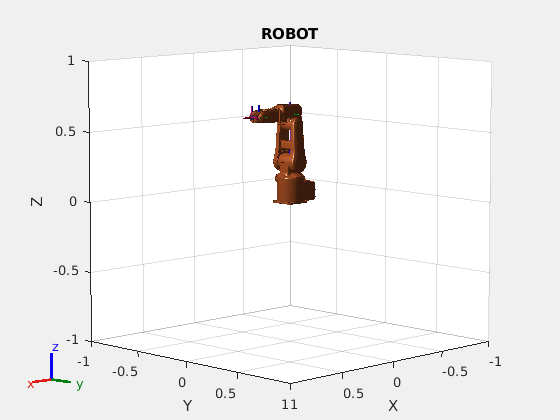

robo = loadrobot('abbIrb120');
ax = show(robo);
title(ax,'ROBOT');
hold('on');

pts = readtable('DataScience/project/archive/robot_inverse_kinematics_dataset.csv');
pts

pts = 15000×9 table
      q1         q2       q3       q4        q5       q6         x           y         z  
    _______    ______    ____    ______    ______    _____    ________    _______    _____

      -1.51    -0.763    1.85    -0.817     0.912     2.32     -0.0947       0.15    0.301
      -2.84      0.52    1.58     -1.27     -1.39    0.617       0.142       -0.1    0.225
      -1.23     0.695    1.22     -1.13    0.0343     6.27     -0.0833      0.223    0.206
      -1.99      1.06    1.74     -1.76     -1.24     4.76       0.135    -0.0314     0.37
       1.05     0.836    1.34     -1.89     0.484     4.38      -0.056     -0.229     0.26
      0.762    -0.717    1.86      1

x = pts(:,7);
y = pts(:,8);
z = pts(:,9);

x_d = table2array(x);
y_d = table2array(y);
z_d = table2array(z);

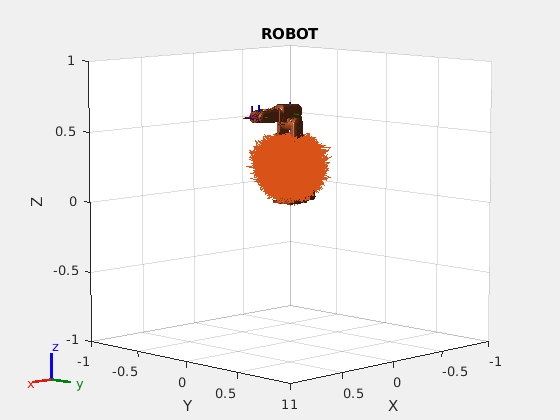

plot3(ax,x_d,y_d,z_d)

a=[1 2 3];

Array indices must be positive integers or logical values.

**RANDOM JOINT CONFIGURATION FROM GIVEN DATASET**

 
config = pts(20,:);
config = table2array(config);

disp(config);

    1.4600    0.1840    1.5300   -2.1000    0.0114    0.1340   -0.0187   -0.1880    0.2350




home_config = homeConfiguration(robo)

home_config = 1×6 struct array with fields:
    JointName
    JointPosition


disp(home_config);

  1×6 struct array with fields:

    JointName
    JointPosition



for i = 1:6
    home_config(i).JointPosition = config(7-i);
    disp(home_config(i).JointName);
end

joint_1
joint_2
joint_3
joint_4
joint_5
joint_6


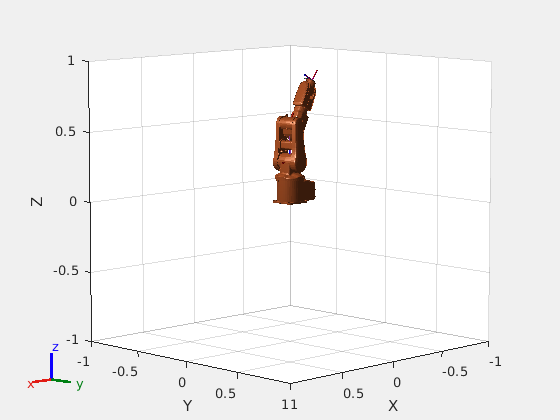

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robo,home_config) 

robo.showdetails

--------------------
Robot: (8 bodies)

 Idx     Body Name            Joint Name            Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------            ----------            ----------     ----------------   ----------------
   1          base        base_link-base                 fixed         base_link(0)   
   2        link_1               joint_1              revolute         base_link(0)   link_2(3)  
   3        link_2               joint_2              revolute            link_1(2)   link_3(4)  
   4        link_3               joint_3              revolute            link_2(3)   link_4(5)  
   5        link_4               joint_4              revolute            link_3(4)   link_5(6)  
   6        link_5               joint_5              revolute            link_4(5)   link_6(7)  
   7        link_6               joint_6              revolute            link_5(6)   tool0(8)  
   8         tool0          joint6-tool0                 fixed            link_6